# Drone Payload Structure Design and Analysis

In this project, you are optimizing drone arm design, including geometry and material selection, to maximize payload capacity while ensuring structural integrity under motor-induced loads. You will use MATLAB to perform force balance analysis and finite element modeling to quantitatively support your design solution.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Gather your starter assumptions and load the material properties into MATLAB.

- Propose at least two drone arm designs

- Perform a thrust-to-weight analysis to evaluate each of your designs across all material options. Your design must meet a minimum payload requirement and safety standards.

- Perform finite element analysis across all design and material options.

- Recommend a final design solution.

## Break Down the Problem

In the space below, define the problem statement:

    The objective is to select a drone arm geometry and material combination that maximizes payload capacity while satisfying the minimum thrust-to-weight ratio and maintaining an acceptable structural safety factor under motor loading.

List the requirements, constraints, and success criteria for the project:

- The drone must support a minimum payload of 0.5 kg.

- The drone must meet a thrust-to-weight ratio of at least 2:1.

- The quadcopter configuration uses 4 motors and 4 propellers.

- Each motor can provide up to 1 kg of thrust.

- The total mass of the drone without arms or payload is 1 kg.

- The design must use at least two distinct arm geometries.

- The arm design must be evaluated across the available material options.

- The final selected design must satisfy the required payload and flight safety constraints.

- The structural design must maintain an acceptable factor of safety, with the target engineering range taken as approximately ~1.5-2+.

- Material cost should be considered as an optional optimization criterion in addition to the required performance and safety checks.

What is your proposed solution?

- The proposed solution is to compare two distinct drone arm geometries and evaluate them across the available material options using thrust-to-weight analysis and a single-arm finite element model to identify the combination that maximizes payload capacity while satisfying the required flight and structural safety constraints.

List the steps you will need to take to achieve your proposed solution:

- Gather Starter Assumptions and Load Properties into MATLAB

- Develop at Least Two Distinct Drone Arm Designs in CAD or by Hand

- Write a MATLAB Function to Perform a Thrust-to-Weight Analysis Across All Design and Material Options

- Create a 3D Model of One Drone Arm Using CAD Software of Your Choice

- Import Your Model into MATLAB and Perform FEA

- Report the Overall Maximum Displacement, Maximum Stress, and Factor of Safety for Each Design and Material Combination, Including Visualizations of the X-, Y-, and Z-Displacement and von Mises Stress

- Recommend a Final Drone Arm Design That Meets All Required Constraints

What challenges do you face in the process of achieving the solution?

- The analysis is simplified to a single-arm structural model rather than the full four-arm drone assembly.

- Material properties are treated as homogeneous and isotropic, which is an approximation for composite and wood materials.

- The arm geometry and loading conditions are idealized rather than fully representing the complete flight environment.

- The FEA model captures only the dominant motor thrust and motor weight loading, while other real-world effects such as vibration, landing loads, and aerodynamic forces are not included.

- The design must balance payload capacity, structural stiffness, and material cost under the stated assumptions.

## Task 1: Gather your starter assumptions and load material properties

Load the provided `droneArmMaterials.mat` file into MATLAB. This contains a data struct with the material properties for six different materials commonly used for drones (carbon fiber composite, aluminum alloy, fiberglass composite, PLA plastic, ABS plastic, and wood). For each material, you have been provided the following information:

- Density ($\rho$), in $\frac{\mathrm{kg}}{m^3 }$

- Young's Modulus ($E$) in Pa

- Poisson's ratio ($\nu$), unitless

- Yield strength, in Pa

- Average cost per meter in US dollars

For this project, you can assume the following design parameters:

- Quadcopter drone with 4 motors and 4 propellers

- Each motor can provide up to 1kg thrust

- Acceleration due to gravity: $g=9\ldotp 81\;\frac{m}{s^2 }$ 

- Total weight of the drone components without the arms or the payload: 1kg 

The breakdown of the weight of each drone component is as follow:

- Battery = 0.3kg

- Each motor = 65g, 4 motors = 0.26kg

- Each propeller = 10g, 4 propellers = 0.04 kg

- Each electronic speed controller = 30g, 4 electronic speed controllers = 0.12 kg

- Flight controller and electronics = 0.05kg

- Receiver/GPS = 0.03kg

- Drone frame (center body) excluding arms = 0.2kg

clc; clear; close all;

% Load material properties for the six drone arm materials
load droneArmMaterials.mat;

% Define drone component masses (kg)
batteryMass = 0.30; % Battery
motorMass = 65 / 1000; % Each motor
numberOfMotors = 4; % Number of motors
totalMotorMass = motorMass * numberOfMotors;

propellerMass = 10 / 1000; % Each propeller
numberOfPropellers = 4; % Number of propellers
totalPropellerMass = propellerMass * numberOfPropellers;

speedControllerMass = 30 / 1000; % Each electronic speed controller
numberOfSpeedControllers = 4; % Number of electronic speed controllers
totalSpeedControllerMass = ...
    speedControllerMass * numberOfSpeedControllers;

flightControllerMass = 0.05; % Flight controller and electronics
receiverGPSMass = 0.03; % Receiver/GPS
droneFrameMass = 0.20; % Drone frame excluding arms

% Calculate total mass of the drone without arms or payload
totalDroneMassWithoutArmsOrPayload = ...
    batteryMass + ...
    totalPropellerMass + ...
    totalMotorMass + ...
    totalSpeedControllerMass + ...
    flightControllerMass + ...
    receiverGPSMass + ...
    droneFrameMass;

% Define general design parameters
gravity = 9.81; % Acceleration due to gravity (m/s^2)
motorThrustCapacity = 1; % Maximum thrust per motor (kgf)
totalThrust = numberOfMotors * motorThrustCapacity;
minimumPayload = 0.5; % Minimum required payload (kg)
requiredThrustToWeightRatio = 2; % Required thrust-to-weight ratio (2:1)
numberOfArms = 4; % Number of arms on the quadcopter

## Task 2: Propose at least two drone arm designs

Develop at least two distinct drone arm designs by drawing clear, neatly labeled sketches that show key geometric features, including:

- Overall shape (e.g. beam, tube, truss structure)

- Dimensions (length, width, thickness)

- Motor mount location

- Where the arm connects to the drone body 

The two designs should be meaningfully different from each other (e.g. different geometries or structural strategies) and not just small variations of the same idea.

Navigate to the 'Insert' tab and insert pictures of your sketches in the space below (hand-drawn or digital). Include a short design description for each sketch that includes:

- Geometry (e.g. solid beam, hollow tube, beam with trusses)

- Why you chose this design

- How it might perform under load

**Note: All dimensions and measurements for the drone arm designs are provided in millimeters (mm) for consistency.**

**Drone Arm Design 1:**

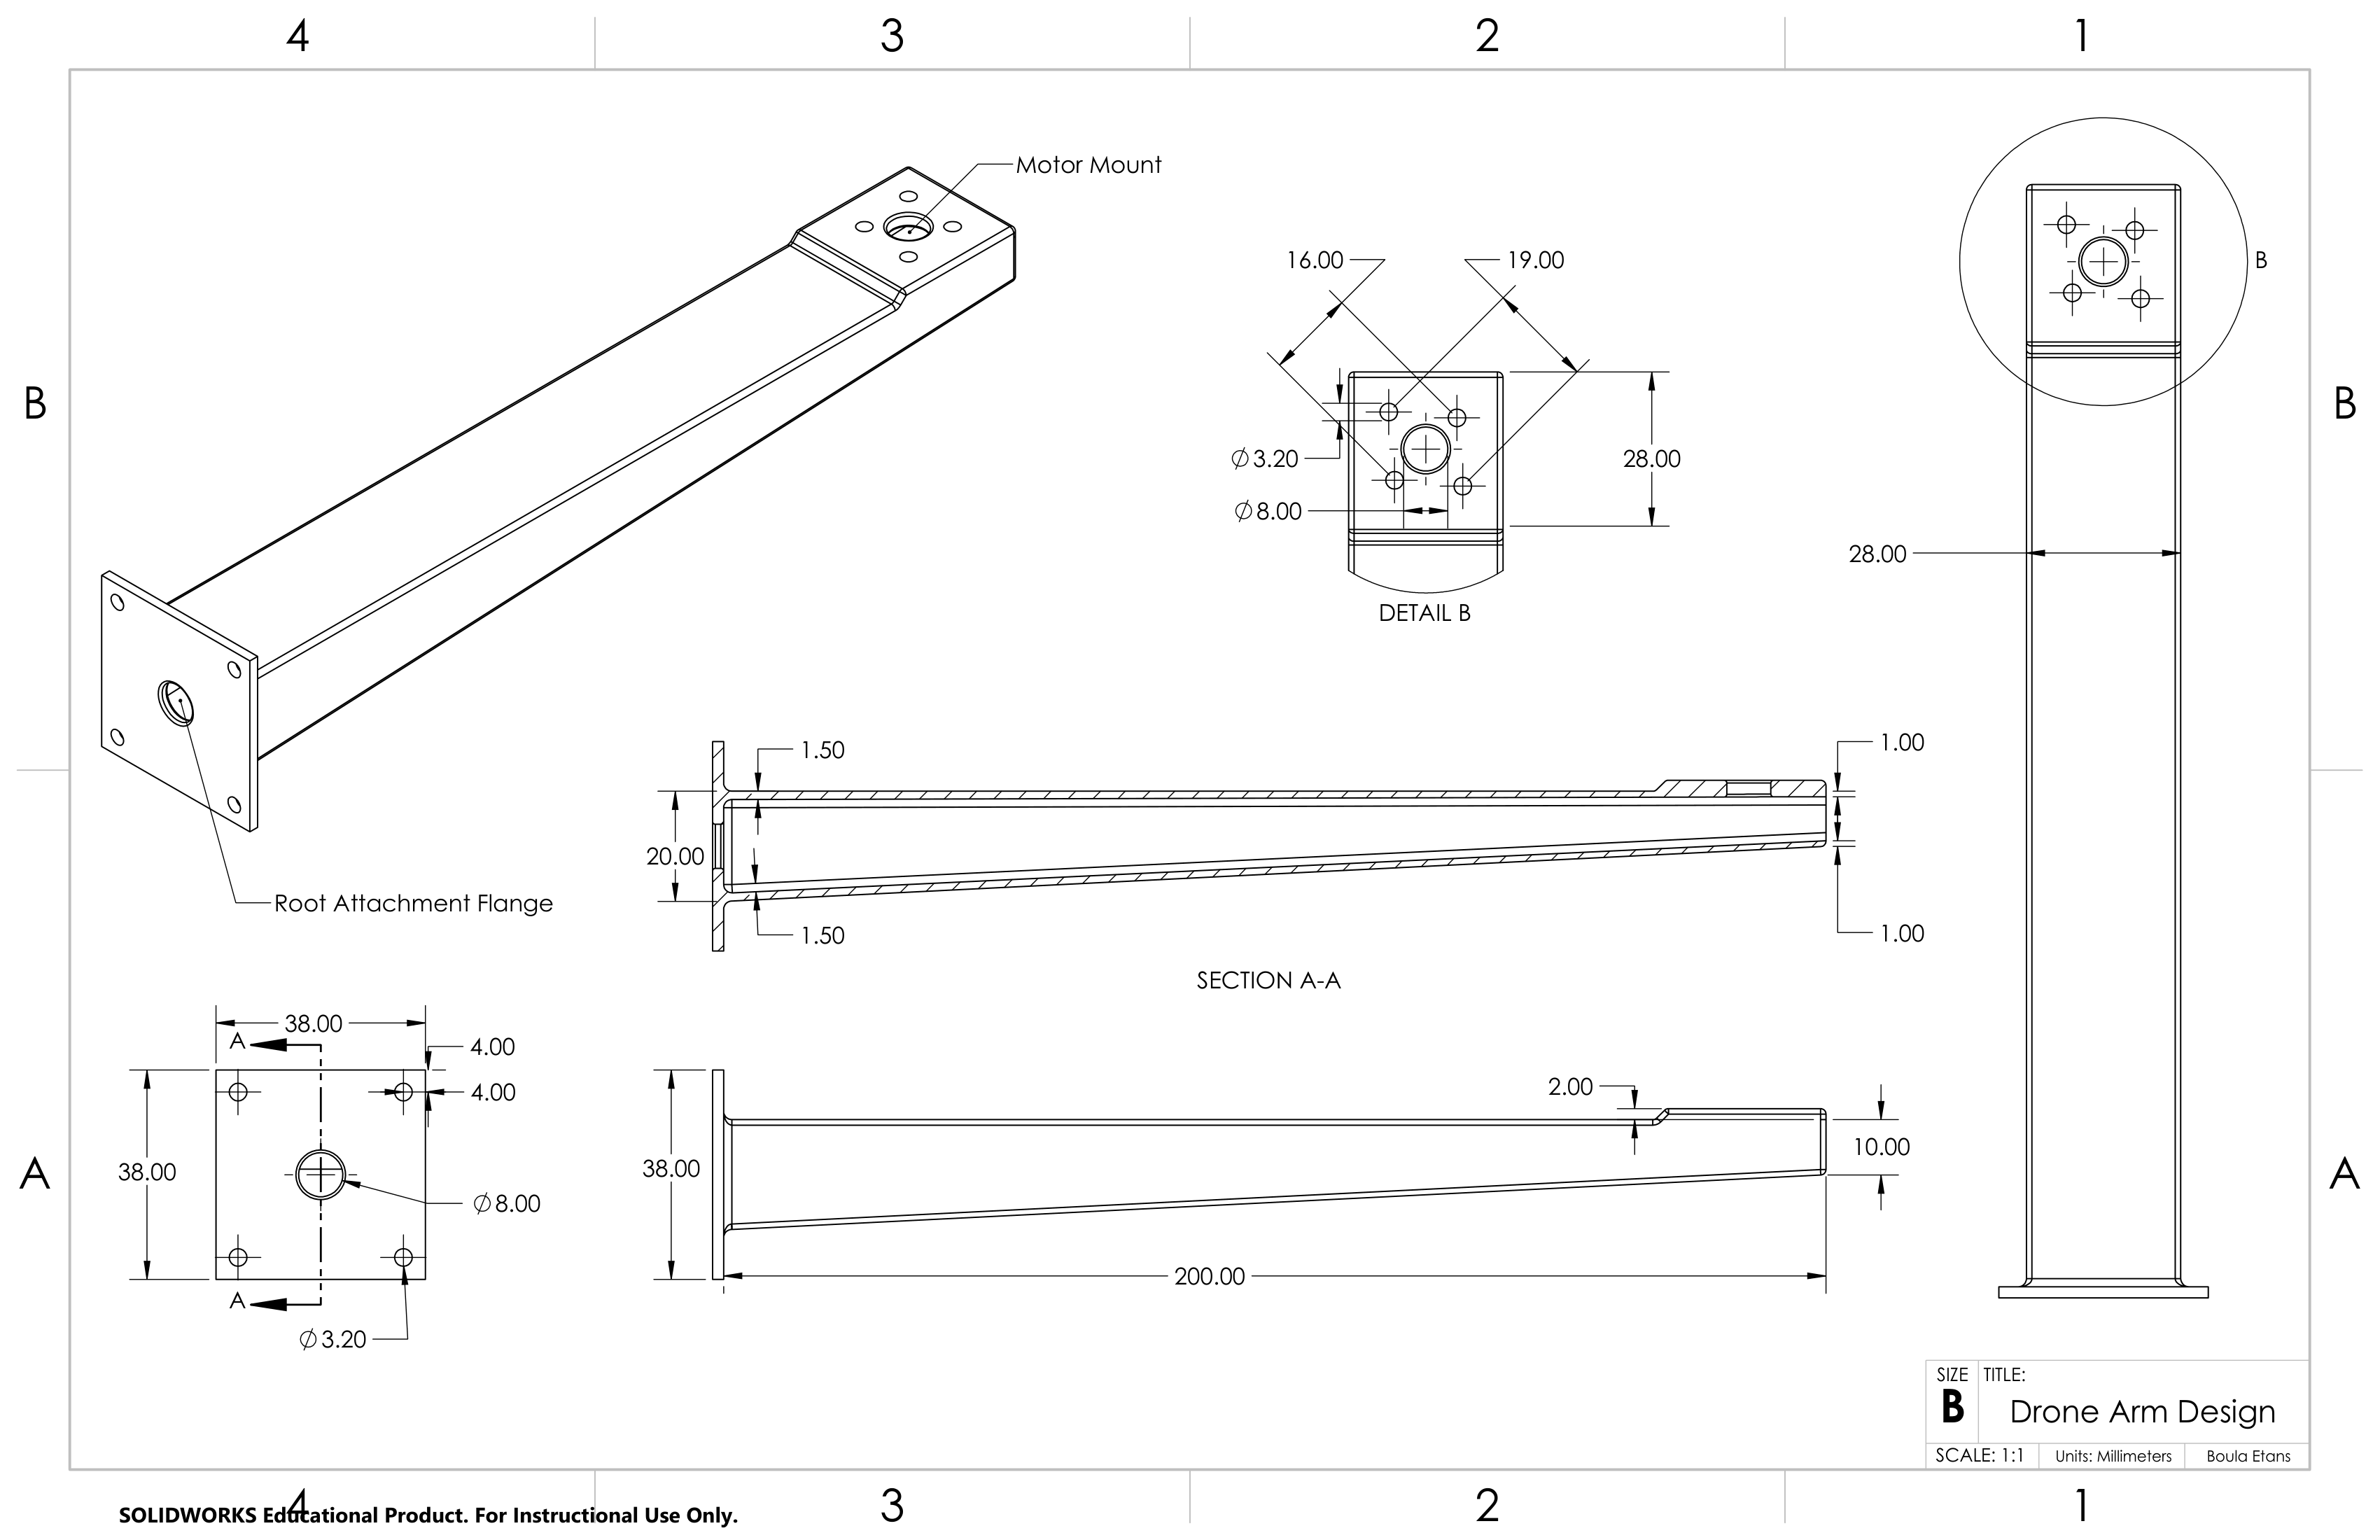

**Geometry: **A tapered hollow rectangular tube spanning a total length of 200.00 mm. The structure originates at the base with a 38.00 mm by 38.00 mm square attachment flange and a profile measuring 28.00 mm in width and 20.00 mm in height, featuring a wall thickness of 1.50 mm. It gracefully tapers toward the distal end to a profile measuring 28.00 mm in width and 10.00 mm in height, with a reduced wall thickness of 1.00 mm. The arm terminates in a 28.00 mm by 28.00 mm square motor mount platform positioned 2.00 mm above the top edge of the tapered body.

**Reasoning: **This geometry is chosen to optimize the strength-to-weight ratio. A drone arm acts as a cantilever beam, meaning the highest bending moments occur at the base where it attaches to the frame, while the stresses at the motor end are significantly lower. By tapering both the overall profile and the wall thickness, the design strategically places material only where it is needed to bear the load, stripping away unnecessary dead weight at the tip.

**Analysis:** Under the 1 kg upward thrust load, this arm is expected to show excellent bending stiffness at the root, keeping overall deflections low. Because the tapered design minimizes the arm's total mass, it will consume less of the drone's 2 to 1 thrust-to-weight budget, maximizing the remaining capacity available to safely carry the required 0.5 kg payload.

**Drone Arm Design 2:**

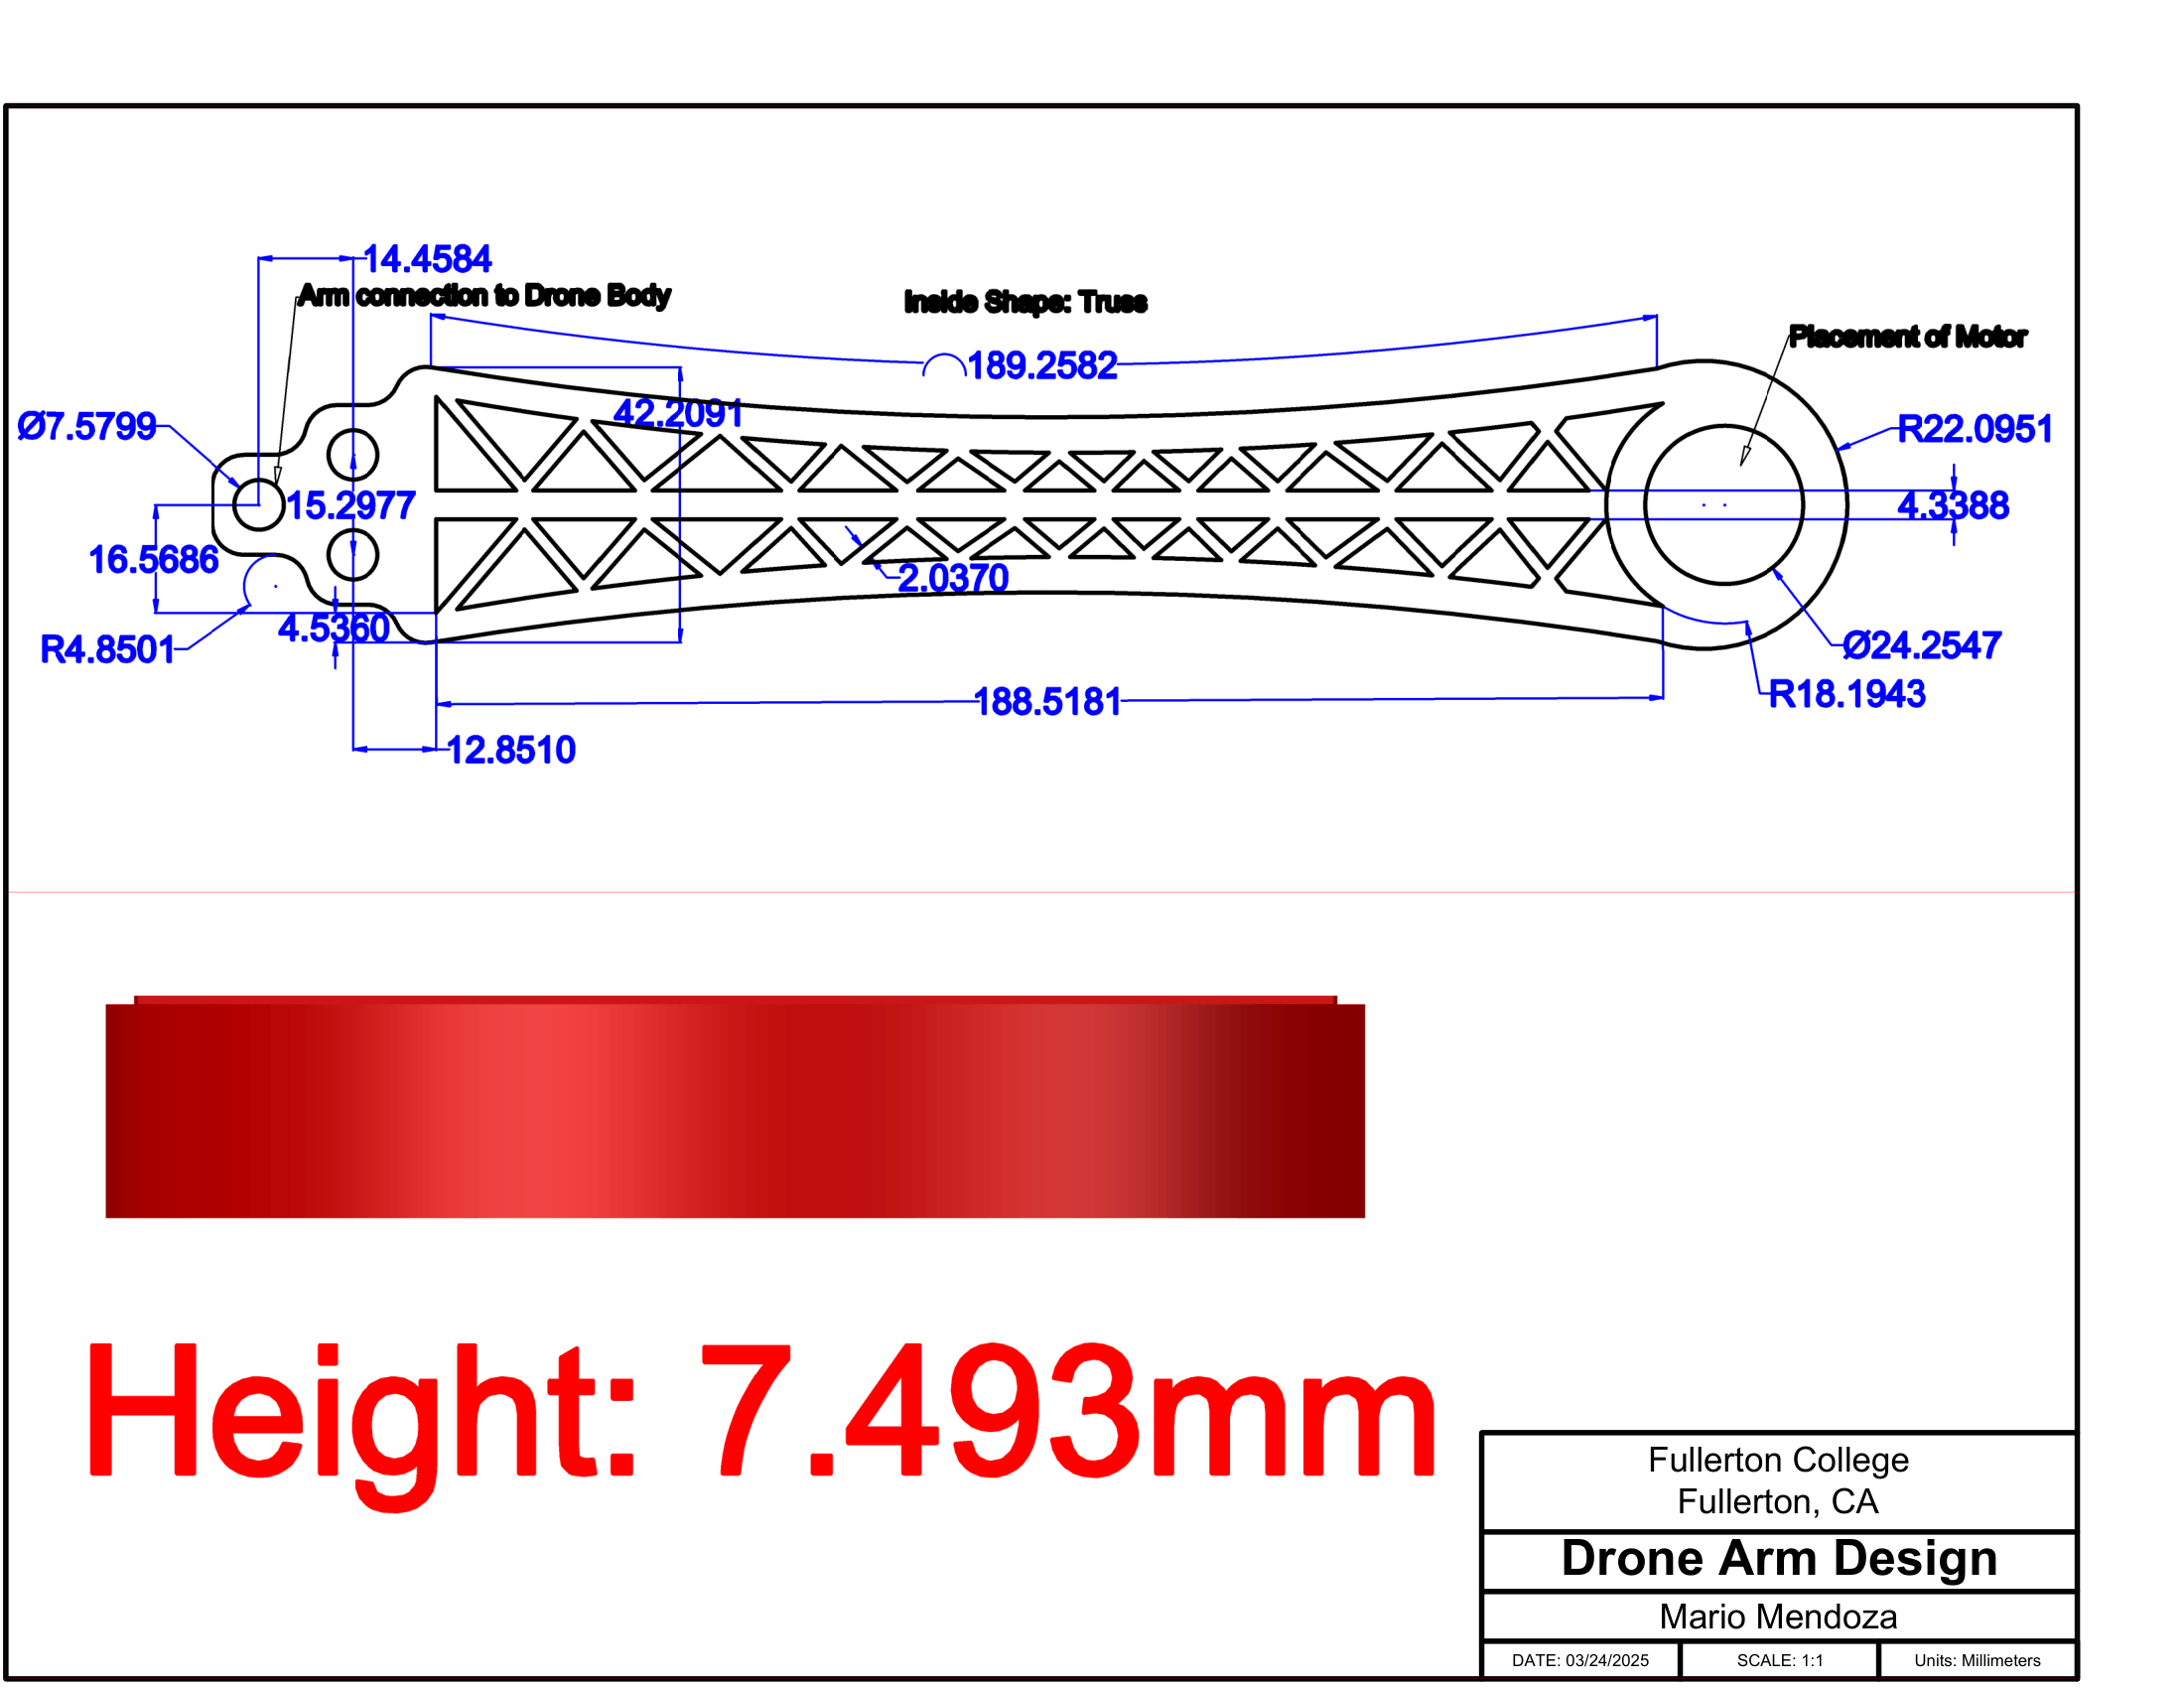

**Geometry: **PLA, hollow truss-shaped inside, with the thickness of each truss arm/branch being approx. 2.0370  mm. The outside walls feature a continuous inward curve (with a radius of 189.2582 mm), causing the internal truss structure to narrow towards the middle before widening again as it approaches the motor housing. Holes for the arm connection are placed in a triangle shape. The total height of the drone arm is 7.493 mm throughout. 

**Reasoning: **Truss shapes of the inside part of the drone arm are designed for stabilization, optimal strength, material efficiency, and weight reduction. This drone arm design also allows for creativity of the user or any future re-designers regarding the placement of the motor. The arm connection to the body of the drone is also shaped in a triangle to ensure the placement is optimally secured and geometrically rigid. 

**Analysis: **While the truss structure of the drone arm design will provide strength and stiffness, the region between the arm connection and the starting portion of where the curvature begins might cause future problems; further optimization might be required in order to avoid a snap of that region.

## Task 3: Perform thrust-to-weight analysis across all design and material options

Write a MATLAB function that will perform a thrust-to-weight analysis across all design and material options. This analysis will help you evaluate which drone arm design and which material optimizes payload capacity while meeting suggested safety requirements. 

- Your design must support a minimum payload of 0.5kg. 

- Your design must meet a thrust-to-weight ratio of at least 2:1 to ensure safe and stable flight. This safety standard is widely used in drone design. Conceptually, it means that the drone's maximum thrust must be at least twice its weight. This ensures stable hovering and maneuvering with a safety margin. Note that the thrust-to-weight safety margin is a system-level safety standard for drone flight that is distinct from the structural safety factor of the drone arms (which you will evaluate later through finite element analysis).

- Your goal is calculate maximum payload capacity for each design and material option (i.e. what is the heaviest payload your drone design could carry while still allowing the drone to safely take off?)

Ensure that the results of your analysis can be readily interpreted, e.g. in the form of a summary table or plot.

Note: if you have two drone arm designs, the expected output should be 12 payload capacity estimates (2 designs across 6 materials options).

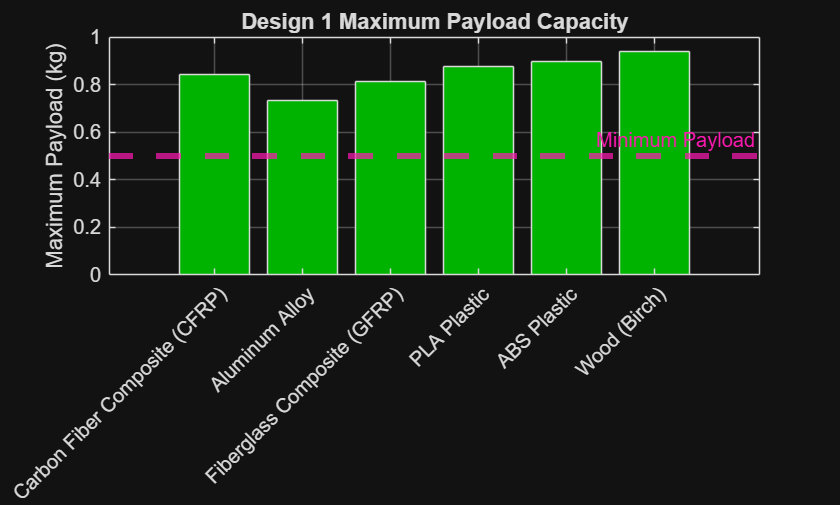

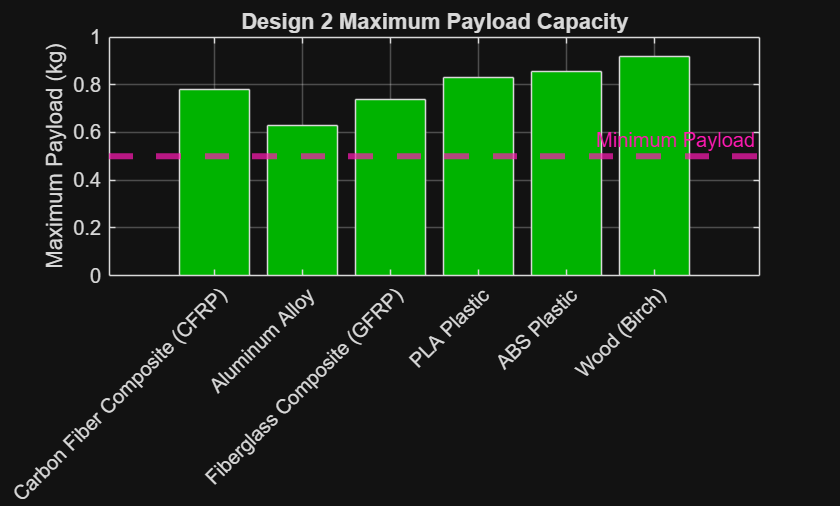


      DESIGN 1 MAXIMUM PAYLOAD TABLE

               Material                TotalArmMass_kg    MaximumPayload_kg
    _______________________________    _______________    _________________

    "Carbon Fiber Composite (CFRP)"        0.15893             0.84107     
    "Aluminum Alloy"                       0.26819             0.73181     
    "Fiberglass Composite (GFRP)"          0.18872             0.81128     
    "PLA Plastic"                          0.12416             0.87584     
    "ABS Plastic"                          0.10429             0.89571     
    "Wood (Birch)"                        0.059597              0.9404     


Design 1 Maximum Payload Summary:

Design 1 Passes for:
 Carbon Fiber Composite (CFRP)
 Aluminum Alloy
 Fiberglass Composite (GFRP)
 PLA Plastic
 ABS Plastic
 Wood (B

% Define arm volumes from Task 2
armVolume1 = 2.483207e-5;
armVolume2 = 3.4295614e-5;

% Store both design volumes for comparison
armVolumes = [armVolume1, armVolume2];

% Define names for each drone arm design
designNames = ["Design 1", "Design 2"];

% Perform thrust-to-weight analysis for all designs and materials
task3Results = thrustToWeightAnalysis( ...
    armVolumes, ...
    designNames, ...
    materials, ...
    totalDroneMassWithoutArmsOrPayload, ...
    totalThrust, ...
    minimumPayload, ...
    requiredThrustToWeightRatio, ...
    numberOfArms);


function task3Results = thrustToWeightAnalysis( ...
    armVolumes, designNames, materials, ...
    totalDroneMassWithoutArmsOrPayload, ...
    totalThrust, minimumPayload, ...
    requiredThrustToWeightRatio, ...
    numberOfArms)

    % Determine the number of materials and design-material combinations
    numberOfMaterials = length(materials);
    numberOfCombinations = length(armVolumes) * numberOfMaterials;

    % Initialize arrays for storing analysis results
    designNameResults = strings(numberOfCombinations, 1);
    materialNameResults = strings(numberOfCombinations, 1);
    armDensity = zeros(numberOfCombinations, 1);
    totalArmMass = zeros(numberOfCombinations, 1);
    maximumPayload = zeros(numberOfCombinations, 1);
    resultStatus = strings(numberOfCombinations, 1);

    % Calculate the maximum allowable drone mass based on the required thrust-to-weight ratio
    maximumAllowedTotalMass = totalThrust / requiredThrustToWeightRatio;

    % Initialize combination counter
    combinationNumber = 1;

    % Loop through each arm design
    for designNumber = 1:length(armVolumes)

        % Get the current arm volume
        currentArmVolume = armVolumes(designNumber);

        % Loop through each material option
        for materialNumber = 1:numberOfMaterials

            % Store current design and material information
            designNameResults(combinationNumber) = designNames(designNumber);
            materialNameResults(combinationNumber) = string(materials(materialNumber).name);
            armDensity(combinationNumber) = materials(materialNumber).rho_kg_m3;

            % Calculate the total mass of all four drone arms
            totalArmMass(combinationNumber) = ...
                currentArmVolume * armDensity(combinationNumber) * numberOfArms;

            % Calculate the maximum payload capacity for the current design-material combination
            maximumPayload(combinationNumber) = ...
                maximumAllowedTotalMass - ...
                totalDroneMassWithoutArmsOrPayload - ...
                totalArmMass(combinationNumber);

            % Calculate the total drone mass including the minimum payload
            totalDroneMass = ...
                totalDroneMassWithoutArmsOrPayload ...
                + totalArmMass(combinationNumber) ...
                + minimumPayload;

            % Check if the design satisfies payload and thrust-to-weight requirements
            if maximumPayload(combinationNumber) >= minimumPayload && ...
                    totalThrust / totalDroneMass >= requiredThrustToWeightRatio

                resultStatus(combinationNumber) = "PASS";

            else

                resultStatus(combinationNumber) = "FAIL";

            end

            % Move to the next design-material combination
            combinationNumber = combinationNumber + 1;

        end
    end

    % Create a complete table containing all internal analysis results
    fullTable = table( ...
        designNameResults, ...
        materialNameResults, ...
        armDensity, ...
        totalArmMass, ...
        maximumPayload, ...
        'VariableNames', { ...
            'Design', ...
            'Material', ...
            'Density_kg_m3', ...
            'TotalArmMass_kg', ...
            'MaximumPayload_kg'});

    % Save internal results for later use in Task 5
    task3Results.designNames = designNameResults;
    task3Results.materialNames = materialNameResults;
    task3Results.maximumPayload = maximumPayload;
    task3Results.resultStatus = resultStatus;

    % Extract display tables for each individual design
    design1Display = fullTable( ...
        fullTable.Design == "Design 1", ...
        {'Material', 'TotalArmMass_kg', 'MaximumPayload_kg'});
    design2Display = fullTable( ...
        fullTable.Design == "Design 2", ...
        {'Material', 'TotalArmMass_kg', 'MaximumPayload_kg'});
    
    % Create a payload comparison plot for each design
    for designNumber = 1:length(designNames)

        % Create a new figure for the current design
        figure;

        % Identify results belonging to the current design
        designIndex = designNameResults == designNames(designNumber);
        designPayload = maximumPayload(designIndex);
        designStatus = resultStatus(designIndex);
        designMaterials = materialNameResults(designIndex);

        % Create bar plot of maximum payload capacity
        barHandle = bar(designPayload);

        % Initialize colors based on pass or fail status
        plotColors = zeros(numberOfMaterials, 3);

        % Assign green to passing materials and red to failing materials
        for materialNumber = 1:numberOfMaterials

            if designStatus(materialNumber) == "PASS"
                plotColors(materialNumber, :) = [0 0.7 0];

            else
                plotColors(materialNumber, :) = [0.9 0 0];

            end

        end

        % Apply colors to the bar chart
        barHandle.FaceColor = "flat";
        barHandle.CData = plotColors;

        % Format x-axis labels
        xticks(1:numberOfMaterials);
        xticklabels(designMaterials);
        xtickangle(45);

        % Add plot labels and title
        ylabel("Maximum Payload (kg)");
        title(designNames(designNumber) + " Maximum Payload Capacity");

        % Display minimum payload requirement
        yline(minimumPayload, "--", "Minimum Payload", ...
            "Color", [1 0.1 0.7], "LineWidth", 3);

        % Set plot limits and enable grid
        ylim([0 1]);
        yticks(0:0.2:1);
        grid on;

    end

    % Display Design 1 results
    fprintf("\n");
    fprintf("========================================\n");
    fprintf("      DESIGN 1 MAXIMUM PAYLOAD TABLE\n");
    fprintf("========================================\n\n");
    disp(design1Display);

    % Design 1 Summary:
    fprintf("\nDesign 1 Maximum Payload Summary:\n");

    design1Payload = maximumPayload(1:numberOfMaterials);
    design1Materials = materialNameResults(1:numberOfMaterials);

    % Design 1 passes
    fprintf("\nDesign 1 Passes for:\n");

    design1Passed = false;

    for i = 1:numberOfMaterials
        if design1Payload(i) >= minimumPayload
            fprintf(" %s\n", design1Materials(i));
            design1Passed = true;
        end
    end

    if ~design1Passed
        fprintf(" No materials passed\n");
    end

    % Design 1 fails
    fprintf("\nDesign 1 Fails for:\n");

    design1Failed = false;

    for i = 1:numberOfMaterials
        if design1Payload(i) < minimumPayload
            fprintf(" %s\n", design1Materials(i));
            design1Failed = true;
        end
    end

    if ~design1Failed
        fprintf(" No materials failed\n");
    end


    % Display Design 2 results
    fprintf("\n");
    fprintf("========================================\n");
    fprintf("      DESIGN 2 MAXIMUM PAYLOAD TABLE\n");
    fprintf("========================================\n\n");
    disp(design2Display);

    % Design 2 Summary:
    fprintf("\nDesign 2 Maximum Payload Summary:\n");

    design2Payload = maximumPayload(numberOfMaterials+1:2*numberOfMaterials);
    design2Materials = materialNameResults(numberOfMaterials+1:2*numberOfMaterials);

    % Design 2 passes
    fprintf("\nDesign 2 Passes for:\n");

    design2Passed = false;

    for i = 1:numberOfMaterials
        if design2Payload(i) >= minimumPayload
            fprintf(" %s\n", design2Materials(i));
            design2Passed = true;
        end
    end

    if ~design2Passed
        fprintf(" No materials passed\n");
    end

    % Design 2 fails
    fprintf("\nDesign 2 Fails for:\n");

    design2Failed = false;

    for i = 1:numberOfMaterials
        if design2Payload(i) < minimumPayload
            fprintf(" %s\n", design2Materials(i));
            design2Failed = true;
        end
    end

    if ~design2Failed
        fprintf(" No materials failed\n");
    end
end

## Task 4: Perform finite element analysis across all design and material options

Perform finite element analysis (FEA) across all design and material options to evaluate the structural safety factor of your drone arm design. To simplify the task, you will perform the FEA only on a single drone arm.

Using a CAD software of your choice, first create a 3D model of one drone arm for each of your designs. Be sure your model can be exported as a STEP or STL file for analysis in MATLAB.

- Recommended CAD software options: Tinkercad, Onshape, Fusion 360, Solidworks (most have free versions)

Import your model into MATLAB and perform FEA. In your FEA model, you should model and apply two loads to the drone arm: upward thrust force from the motor and downward weight of the motor.

- Helpful resources: [online tutorial](https://matlabacademy.mathworks.com/details/introduction-to-finite-element-analysis-with-matlab/otmlfea), documentation for [Structural Mechanics](https://www.mathworks.com/help/pde/structural-mechanics.html) and [Partial Differentiation Equation Toolbox](https://www.mathworks.com/help/pde/index.html?s_tid=CRUX_lftnav), and [example workflow](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html)

For each design and material combination, you should report the overall maximum displacement, maximum stress, and factor of safety and include visualizations of the x-, y-, and z-displacement and Von Mises stress. Ensure that your results are presented for easy interpretation (e.g. present a table with numerical results, clearly labeled subplots for the visualizations).

- The factor of safety compares how strong a material is to how much stress it experiences, indicating whether a design is safe under the given loads. For this project use the equation: $\mathrm{FoS}=\frac{\mathrm{Material}\;\mathrm{Yield}\;\mathrm{Strength}\;\left(\mathrm{Pa}\right)}{\mathrm{Maximum}\;\mathrm{von}\;\mathrm{Mises}\;\mathrm{Stress}}$. Yield strength indicates how much stress a given material can withstand before permanently deforming. Maximum von Mises stress (derived from your FEA model) is a measure of how much stress your design experiences under the applied loads.

- A typical engineering safety margin for FoS is ~1.5-2+

- This [example](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html) demonstrates the plots you are asked to include in your results

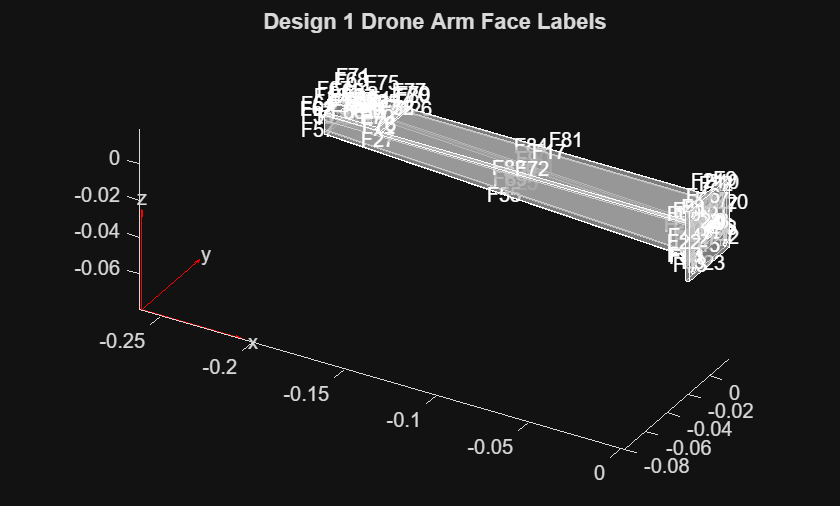

% STEP 1: Import drone arm geometry into MATLAB, visualize the geometry to
% identify  key faces (e.g. tip face)

% Select drone arm design
selectedDesign = "Design 1";
% selectedDesign = "Design 2";

if selectedDesign == "Design 1"

    CADfile = "Design_1_CAD_Model.STEP";
    fixedFaceID = 24;
    motorMountFaceID = 33;
    motorMountFaceArea = 0.00062144;

elseif selectedDesign == "Design 2"

    CADfile = "Design_2_CAD_Model.STL";
    fixedFaceID = 111;
    motorMountFaceID = 82;
    motorMountFaceArea = 0.000866359;

end


% Initialize the finite element model using the geometry
modelFE = femodel(AnalysisType="structuralStatic", Geometry=CADfile);

% Apply STL scaling only for Design 2
if selectedDesign == "Design 2"
    modelFE.Geometry = scale(modelFE.Geometry,0.001);
end

% Generate the finite element mesh
modelFE = generateMesh(modelFE, Hmax=1.5e-3);

% Plot the geometry and display face labels
% This allows the fixed base and motor mount faces to be identified
figure;

pdegplot(modelFE, FaceLabels="on", FaceAlpha=0.5);

view(30, 30);
axis equal;
title(selectedDesign + " Drone Arm Face Labels");

Running FEA for material 1/6: Carbon Fiber Composite (CFRP)


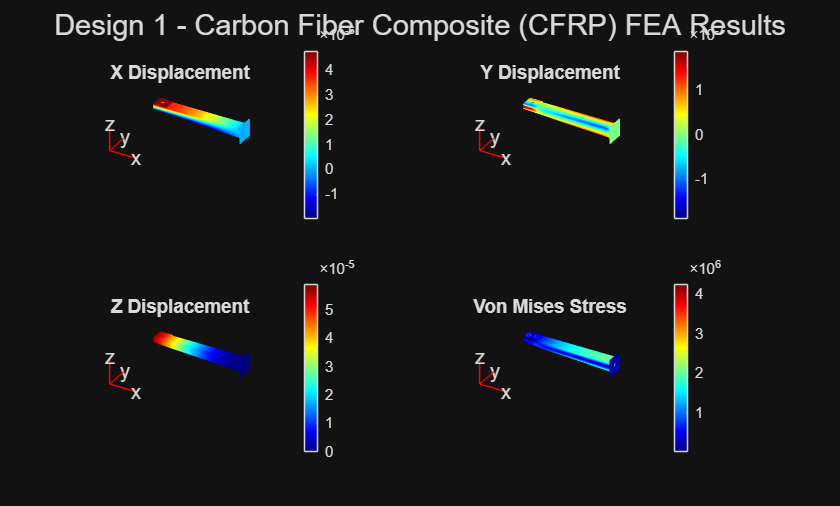

Running FEA for material 2/6: Aluminum Alloy


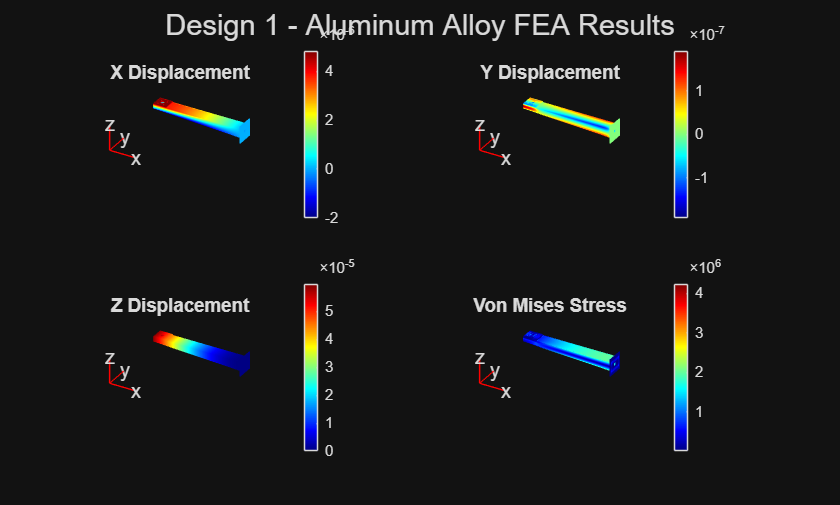

Running FEA for material 3/6: Fiberglass Composite (GFRP)


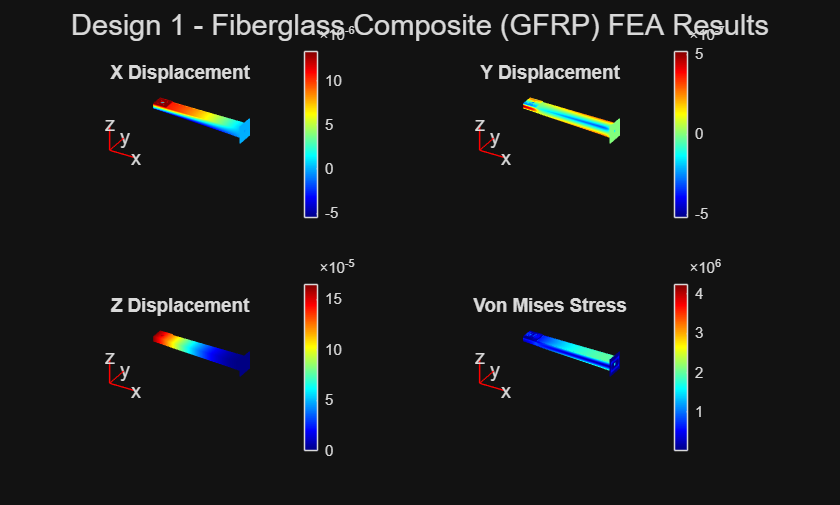

Running FEA for material 4/6: PLA Plastic


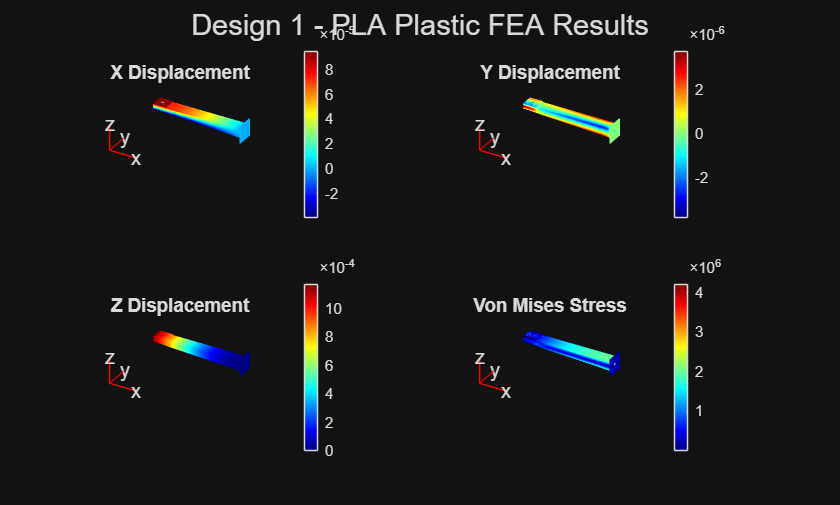

Running FEA for material 5/6: ABS Plastic


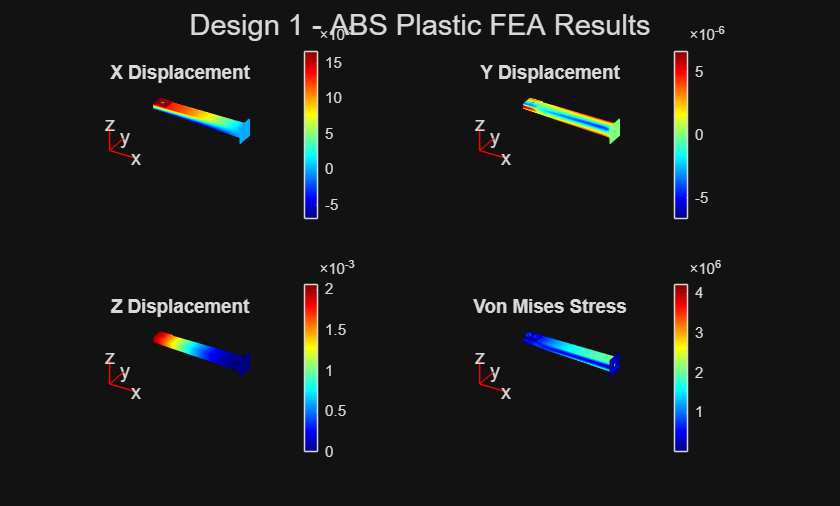

Running FEA for material 6/6: Wood (Birch)


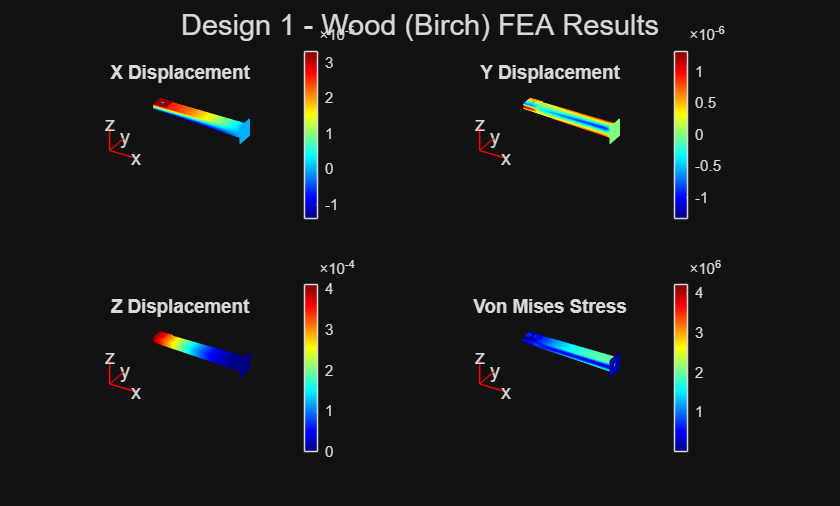


% IMPORTANT:
% Visually confirm from this face-label plot that the selected face IDs
% correspond to the intended physical locations

% STEP 2: Define material properties

% Get the number of available materials
numberOfMaterials = length(materials);

% Initialize arrays for storing FEA results for all six materials
materialName = strings(numberOfMaterials, 1);

maximumDisplacementResults = zeros(numberOfMaterials, 1);
maximumVonMisesStressResults = zeros(numberOfMaterials, 1);
factorOfSafetyResults = zeros(numberOfMaterials, 1);
resultStatus = strings(numberOfMaterials, 1);

% STEP 3: Apply boundary conditions (fix base of arm where it would be
% attached to drone body)

modelFE.FaceBC(fixedFaceID) = ...
    faceBC(Constraint="fixed");


% STEP 4: Apply the upward thrust force (motor force)
% Define the thrust force, convert force to surface traction, apply
% surface traction to the appropriate face in the appropriate direction

% Calculate the upward thrust force from the motor
motorThrustForce_N = motorThrustCapacity * gravity;

% STEP 5: Apply downward motor weight
% Define motor weight, convert to traction, apply to the appropriate face
% in the appropriate direction

% Calculate the downward weight of the motor
motorWeightForce_N = motorMass * gravity;

% Calculate the net force acting in the loading direction
% The upward motor thrust is positive and the downward motor weight is
% negative
netForceZ_N = motorThrustForce_N - motorWeightForce_N;


% IMPORTANT:
% SurfaceTraction is specified in the global Cartesian coordinate system
% The current model assumes that positive global Z is the upward thrust
% direction based on the STEP model coordinate orientation

thrustDirection = [0; 0; 1];

% Calculate the net surface traction
netTractionMagnitude = netForceZ_N / motorMountFaceArea;

% Convert the scalar net traction into a global Cartesian vector
netTraction = thrustDirection * netTractionMagnitude;

% Apply the combined net traction to the motor mount face
modelFE.FaceLoad(motorMountFaceID) = faceLoad(SurfaceTraction=netTraction);


% STEP 6: Solve the FEA model

for materialNumber = 1:numberOfMaterials

    % Print the current material being processed
    fprintf("Running FEA for material %d/%d: %s\n", ...
        materialNumber, numberOfMaterials, string(materials(materialNumber).name));
    drawnow;

    % Get material information from the droneArmMaterials data structure
    materialName(materialNumber) = string(materials(materialNumber).name);

    YoungsModulus = materials(materialNumber).E_Pa;
    PoissonsRatio = materials(materialNumber).nu;
    YieldStrength = materials(materialNumber).yieldStrength_Pa;

    % Assign material properties to the finite element model
    currentModel = modelFE;

    currentModel.MaterialProperties = materialProperties( ...
        YoungsModulus=YoungsModulus, ...
        PoissonsRatio=PoissonsRatio);

    % Solve the FEA model for the current material
    results = solve(currentModel);

    % STEP 7: Get numerical results

    % Calculate displacement magnitude at every mesh node
    displacementMagnitude = sqrt( ...
        results.Displacement.ux.^2 + ...
        results.Displacement.uy.^2 + ...
        results.Displacement.uz.^2);

    % Calculate the maximum displacement magnitude
    maximumDisplacement = max(displacementMagnitude);

    % Calculate the maximum Von Mises stress
    maximumVonMisesStress = max(results.VonMisesStress);

    % Calculate the factor of safety
    factorOfSafety = YieldStrength / maximumVonMisesStress;

    % Store numerical results (conversion of units)
    maximumDisplacementResults(materialNumber) = maximumDisplacement * 1000;
    maximumVonMisesStressResults(materialNumber) = maximumVonMisesStress / 1e6;
    factorOfSafetyResults(materialNumber) = factorOfSafety;

    % Determine whether the design meets the recommended
    % minimum factor of safety of 1.5
    if factorOfSafety >= 1.5
        resultStatus(materialNumber) = "SAFE";
    else
        resultStatus(materialNumber) = "UNSAFE";
    end

    % STEP 8: Visualize your results
    figure;
    sgtitle(selectedDesign + " - " + materialName(materialNumber) + " FEA Results");

    subplot(2,2,1);
    pdeplot3D(results.Mesh, ColorMapData=results.Displacement.ux);
    title("X Displacement");
    xlabel("X");
    ylabel("Y");
    zlabel("Z");
    axis equal;
    colormap(gca, "jet");
    colorbar;

    subplot(2,2,2);
    pdeplot3D(results.Mesh, ColorMapData=results.Displacement.uy);
    title("Y Displacement");
    xlabel("X");
    ylabel("Y");
    zlabel("Z");
    axis equal;
    colormap(gca, "jet");
    colorbar;

    subplot(2,2,3);
    pdeplot3D(results.Mesh, ColorMapData=results.Displacement.uz);
    title("Z Displacement");
    xlabel("X");
    ylabel("Y");
    zlabel("Z");
    axis equal;
    colormap(gca, "jet");
    colorbar;

    subplot(2,2,4);
    pdeplot3D(results.Mesh, ColorMapData=results.VonMisesStress);
    title("Von Mises Stress");
    xlabel("X");
    ylabel("Y");
    zlabel("Z");
    axis equal;
    colormap(gca, "jet");
    colorbar;

end


% Create a summary table containing the key FEA results for all six materials
feaResultsTable = table( ...
    materialName, ...
    maximumDisplacementResults, ...
    maximumVonMisesStressResults, ...
    factorOfSafetyResults, ...
    'VariableNames', { ...
        'Material', ...
        'MaximumDisplacement_mm', ...
        'MaximumVonMisesStress_MPa', ...
        'FactorOfSafety'});

% Save complete internal results for later use in Task 5
task4Results.materialNames = materialName;
task4Results.factorOfSafety = factorOfSafetyResults;
task4Results.resultStatus = resultStatus;


% Display the FEA summary table
fprintf("\n========================================\n        %s FEA RESULTS TABLE\n========================================\n\n", ...
    upper(selectedDesign));


        DESIGN 1 FEA RESULTS TABLE




disp(feaResultsTable);

               Material                MaximumDisplacement_mm    MaximumVonMisesStress_MPa    FactorOfSafety
    _______________________________    ______________________    _________________________    ______________

    "Carbon Fiber Composite (CFRP)"           0.059081                    4.2484                  141.23    
    "Aluminum Alloy"                          0.059894                    4.2349                  64.937    
    "Fiberglass Composite (GFRP)"               0.1655                    4.2546                  70.512    
    "PLA Plastic"                               1.1798                    4.2166                  14.229    
    "ABS Plastic"                               2.0652                    4.2232                  9.4714    
    "Wood (Birch)"                             0.41304                    4.2232                  18


% Display FEA safety summary
fprintf("\n%s FEA Safety Summary:\n\nMaterials passing FEA requirements:\n", ...
    selectedDesign);


Design 1 FEA Safety Summary:

Materials passing FEA requirements:



feaPassed = false;

for i = 1:numberOfMaterials
    if resultStatus(i) == "SAFE"
        fprintf(" %s\n", materialName(i));
        feaPassed = true;
    end
end

 Carbon Fiber Composite (CFRP)
 Aluminum Alloy
 Fiberglass Composite (GFRP)
 PLA Plastic
 ABS Plastic
 Wood (Birch)



if ~feaPassed
    fprintf(" No materials passed\n");
end

fprintf("\nMaterials failing FEA requirements:\n");


Materials failing FEA requirements:



feaFailed = false;

for i = 1:numberOfMaterials
    if resultStatus(i) == "UNSAFE"
        fprintf(" %s\n", materialName(i));
        feaFailed = true;
    end
end

if ~feaFailed
    fprintf(" No materials failed\n");
end

 No materials failed


## Task 5: Optimize the total material cost of the drone arm

Using the results from the thrust-to-weight analysis and finite element analysis, determine which material combination provides the lowest material cost while still meeting the required payload, thrust-to-weight ratio, and Factor of Safety.

Calculate the total material cost for each material option using the average material cost provided in the `droneArmMaterials.mat` file. Compare the valid material options and identify the option that provides the best balance of cost, performance, and structural safety.

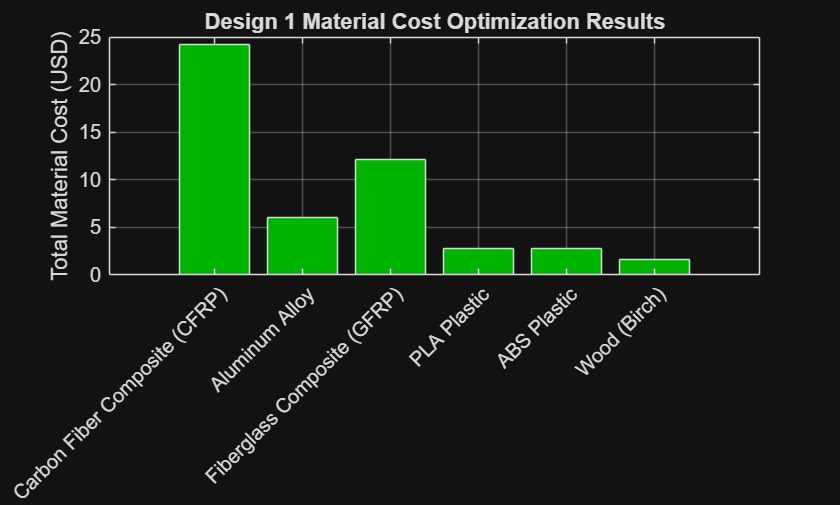

% Number of materials
numberOfMaterials = length(materials);

% Initialize arrays
materialName = strings(numberOfMaterials, 1);
totalMaterialCost = zeros(numberOfMaterials, 1);
maximumPayload = zeros(numberOfMaterials, 1);
factorOfSafety = zeros(numberOfMaterials, 1);

task3Status = strings(numberOfMaterials, 1);
task4Status = strings(numberOfMaterials, 1);
finalStatus = strings(numberOfMaterials, 1);

% Select design evaluated in Task 5

if selectedDesign == "Design 1"

    armLength = 0.202;

elseif selectedDesign == "Design 2"

    armLength = 0.251;

end

% Loop through materials
for materialNumber = 1:numberOfMaterials

    materialName(materialNumber) = string(materials(materialNumber).name);

    % Calculate total material cost for all four arms (rounded to the
    % nearest cent)
    totalMaterialCost(materialNumber) = round( ...
        materials(materialNumber).cost_USD_per_m ...
        * armLength ...
        * numberOfArms, 2);

    % Find selected design result from Task 3
    designIndex = ...
        task3Results.designNames == selectedDesign & ...
        task3Results.materialNames == materialName(materialNumber);

    % Store Task 3 numerical result
    maximumPayload(materialNumber) = ...
        task3Results.maximumPayload(designIndex);

    % Store Task 3 status internally
    task3Status(materialNumber) = ...
        task3Results.resultStatus(designIndex);

    % Find material result from Task 4
    materialIndex = ...
        task4Results.materialNames == materialName(materialNumber);

    % Store Task 4 numerical results
    factorOfSafety(materialNumber) = ...
        task4Results.factorOfSafety(materialIndex);

    % Store Task 4 status internally
    task4Status(materialNumber) = ...
        task4Results.resultStatus(materialIndex);

    % Final design decision requires both tasks to pass
    if task3Status(materialNumber) == "PASS" && ...
            task4Status(materialNumber) == "SAFE"

        finalStatus(materialNumber) = "PASS";

    else

        finalStatus(materialNumber) = "FAIL";

    end

end

% Create optimization summary table
optimizationResults = table( ...
    materialName, ...
    totalMaterialCost, ...
    maximumPayload, ...
    factorOfSafety, ...
    'VariableNames', { ...
        'Material', ...
        'TotalMaterialCost_USD', ...
        'MaximumPayload_kg', ...
        'FactorOfSafety'});

% Plot cost comparison
figure;

barHandle = bar(totalMaterialCost);

plotColors = zeros(numberOfMaterials, 3);

for materialNumber = 1:numberOfMaterials

    if finalStatus(materialNumber) == "PASS"

        plotColors(materialNumber, :) = [0 0.7 0];

    else

        plotColors(materialNumber, :) = [0.9 0 0];

    end

end

barHandle.FaceColor = "flat";
barHandle.CData = plotColors;

xticks(1:numberOfMaterials);
xticklabels(materialName);
xtickangle(45);

ylabel("Total Material Cost (USD)");
title(selectedDesign + " Material Cost Optimization Results");

grid on;


% Display numerical optimization results
fprintf("\n========================================\n  %s MATERIAL OPTIMIZATION TABLE\n========================================\n\n", ...
    upper(selectedDesign));


  DESIGN 1 MATERIAL OPTIMIZATION TABLE




disp(optimizationResults);

               Material                TotalMaterialCost_USD    MaximumPayload_kg    FactorOfSafety
    _______________________________    _____________________    _________________    ______________

    "Carbon Fiber Composite (CFRP)"            24.24                 0.84107             141.23    
    "Aluminum Alloy"                            6.06                 0.73181             64.937    
    "Fiberglass Composite (GFRP)"              12.12                 0.81128             70.512    
    "PLA Plastic"                               2.83                 0.87584             14.229    
    "ABS Plastic"                               2.83                 0.89571             9.4714    
    "Wood (Birch)"                              1.62                  0.9404             18.943    




% Find lowest cost material that satisfies all requirements
validOptions = optimizationResults(finalStatus == "PASS", :);

if isempty(validOptions)

    fprintf("\nNo material option satisfies all required constraints.\n");

else

    [lowestCost, lowestIndex] = min(validOptions.TotalMaterialCost_USD);

    fprintf("\nLowest cost material satisfying all requirements:\nMaterial: %s\nMaterial Cost: %.2f USD\n", ...
        validOptions.Material(lowestIndex), lowestCost);

end


Lowest cost material satisfying all requirements:
Material: Wood (Birch)
Material Cost: 1.62 USD


## Interpretation of Results - Final Recommended Design Solution

Using the results of your thrust-to-weight analysis and finite element analysis, recommend a final drone arm design that meets all required constraints. Your recommendation should clearly identify the selected design (arm geometry and material choice), make use of quantitative results to justify your decisions, demonstrate that the design meets the constraints, explain the trade-offs considered, and include comparisons to alternative designs.

    The final recommended drone arm design is **Design 1 manufactured from Carbon Fiber Composite (CFRP)**. This selection was based on a combination of thrust-to-weight performance, structural stiffness, finite element analysis results, and practical engineering considerations. Although the optimization algorithm identified **Wood (Birch)** as the lowest-cost material option that satisfied all defined constraints, the final engineering recommendation differs because the optimization objective only minimized material cost while maintaining the required payload and structural constraints. CFRP provides a stronger overall balance of lightweight construction, stiffness, durability, and realistic drone manufacturing suitability. Design 1 was selected because its **tapered hollow rectangular tube geometry** efficiently distributes material according to the expected loading behavior of a cantilever drone arm. The larger cross-section near the drone-body attachment provides increased resistance against bending stresses, while the reduced cross-section near the motor mount decreases unnecessary mass. Compared with Design 2, Design 1 uses less material volume, resulting in improved payload capacity across all evaluated materials while maintaining structural integrity. The thrust-to-weight analysis demonstrated that Design 1 satisfied the required flight performance constraints for all tested materials. For the selected CFRP configuration, the four drone arms have a total mass of **0.15893 kg** and provide a maximum theoretical payload capacity of **0.84107 kg**, exceeding the required minimum payload of **0.5 kg**. The design also maintained the required **2:1 thrust-to-weight ratio**, confirming that the selected configuration provides sufficient thrust margin for stable flight under the defined assumptions. Finite element analysis further confirmed the structural capability of the CFRP arm under the applied motor thrust and motor weight loading conditions. The CFRP design experienced a maximum displacement of **5.9081 × 10⁻⁵ m (0.0591 mm)** and a maximum von Mises stress of **4.2484 MPa**. Using the calculated yield strength of the material, the resulting **Factor of Safety of 141.23** significantly exceeded the recommended engineering range of approximately 1.5–2. This indicates that the arm has substantial structural margin under the simplified loading conditions used in the simulation. A mesh refinement study was performed during model development to determine an appropriate finite element mesh size that balanced solution accuracy and computational cost. Several mesh sizes were evaluated, and the selected mesh provided stable displacement and stress results while avoiding excessive computational requirements. The final mesh selection was therefore chosen as a compromise between numerical accuracy and practical simulation time. The material comparison highlighted important trade-offs between weight, stiffness, cost, and structural performance. **Wood (Birch)** achieved the highest theoretical payload capacity of **0.9404 kg** and the lowest material cost of **$1.616**, causing the optimization algorithm to select it as the mathematical optimum. However, this result is based on simplified assumptions and does not fully capture practical manufacturing limitations. Wood properties can vary due to grain direction, moisture content, and material quality, which are not represented in the current isotropic material model. Additionally, producing a thin-walled tapered hollow rectangular tube with consistent mechanical properties would be less predictable compared with composite manufacturing methods. Lower-density polymers also achieved higher theoretical payload values, with **ABS reaching 0.89571 kg** and **PLA reaching 0.87584 kg**. However, these materials experienced significantly greater deformation under the applied loading conditions. ABS had a maximum displacement of **0.0020652 m (2.065 mm)**, which is substantially larger than the CFRP displacement of **0.0591 mm**. This difference demonstrates the advantage of CFRP in maintaining structural stiffness while minimizing weight. Aluminum Alloy provided excellent structural performance, with a maximum displacement of **5.9894 × 10⁻⁵ m (0.0599 mm)** and a Factor of Safety of **64.937**. However, its higher density increased the total arm mass to **0.26819 kg**, reducing the maximum payload capacity to **0.73181 kg**. Although aluminum remains a strong engineering option, CFRP provides improved weight efficiency while maintaining similar stiffness performance. The material cost optimization confirmed that all evaluated materials satisfied the required payload and structural constraints. The algorithm selected **Wood (Birch)** because it provided the minimum calculated material cost. However, the final recommendation of **Design 1 with CFRP** reflects a broader engineering evaluation that considers stiffness, deformation resistance, material reliability, and suitability for real-world drone applications. The additional material cost of CFRP (**$24.24**) provides significant improvements in structural confidence and performance, making it the preferred final design solution.

What are some limitations of your work?

    Several limitations should be considered when interpreting these results. First, the finite element analysis was performed on a single drone arm rather than the complete four-arm drone assembly. Therefore, interactions between the arms, central frame, fasteners, and motor mounting hardware were not included. The material models also assume homogeneous and isotropic behavior, which is a simplification for materials such as CFRP and wood that have direction-dependent mechanical properties. The loading conditions were simplified by combining upward motor thrust and downward motor weight into a single net surface traction applied to the motor mounting face. Actual drone operation includes additional forces from vibration, acceleration, landing impacts, aerodynamic effects, and changing flight conditions. The current Factor of Safety calculation only considers yield strength divided by maximum von Mises stress and does not account for fatigue, manufacturing defects, environmental effects, or long-term degradation. Additionally, the accuracy of the FEA results depends on correctly representing the CAD geometry, boundary conditions, and loading directions. The physical locations of the fixed attachment face and motor mounting face were verified from the STEP model, but future analysis should further validate these assumptions using experimental testing.

What are practical next steps?

    Future work should include expanding the FEA model to represent the complete drone assembly, including the central frame, motor mounts, and attachment hardware. Additional loading cases such as vibration, acceleration, impact, and variable thrust conditions should be evaluated to better represent real flight conditions. For the CFRP design specifically, future simulations should incorporate anisotropic composite properties and fiber-direction-dependent material behavior rather than the simplified isotropic assumption used in the current model. Additional geometry optimization could also reduce material usage in low-stress regions while maintaining the required Factor of Safety. Finally, prototype manufacturing and physical testing would provide experimental validation of the predicted structural performance before implementation in a production drone system.